# Exercise 6

clear all; close all; clc;

## Harris Corner Detector

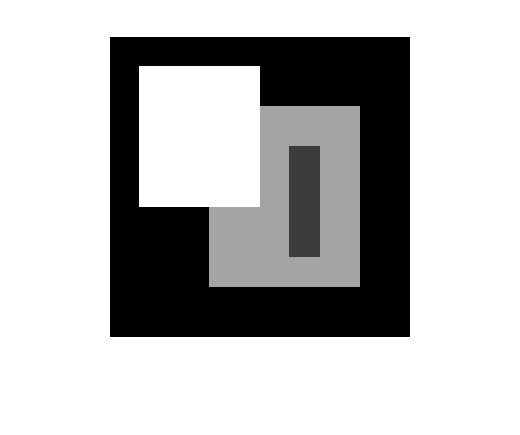

im1 = imread('TestIm1.png');
im1 = rgb2gray(im1);
imshow(im1);

## A

[g, gx] = gaussian1DKernel(0);

## B

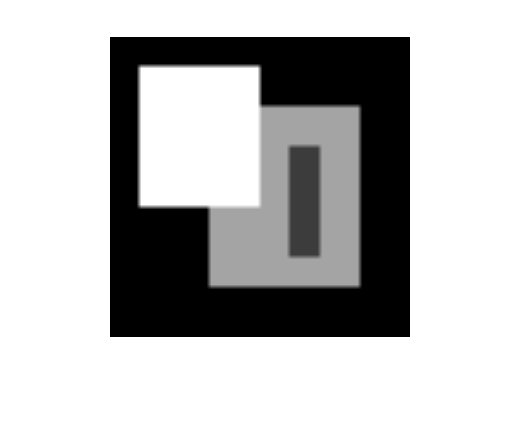

[I, Ix, Iy] = gaussianSmoothing(im1, 5);
imshow(I);

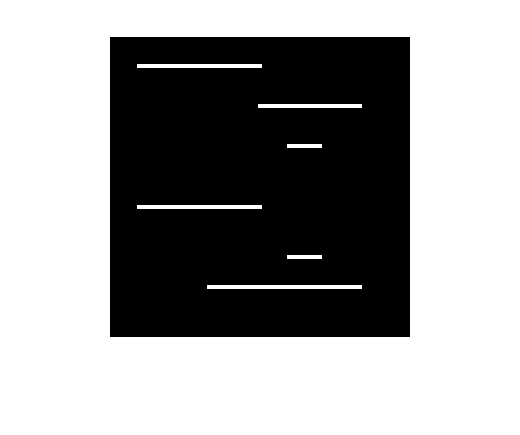

% It looks correct
imshow(Ix);

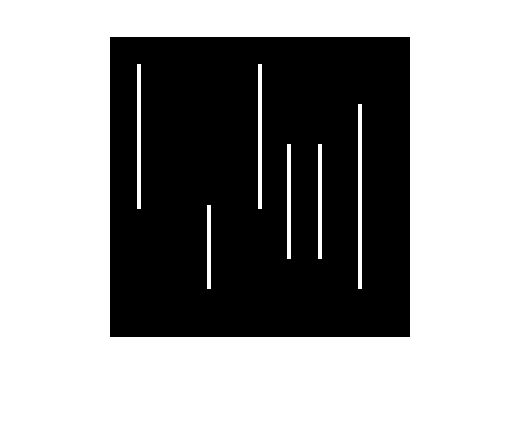

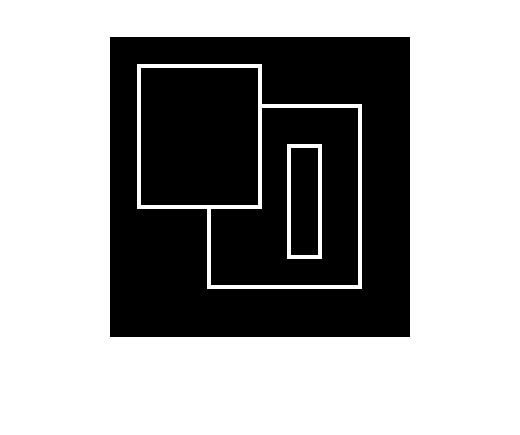

imshow(Iy);

## C

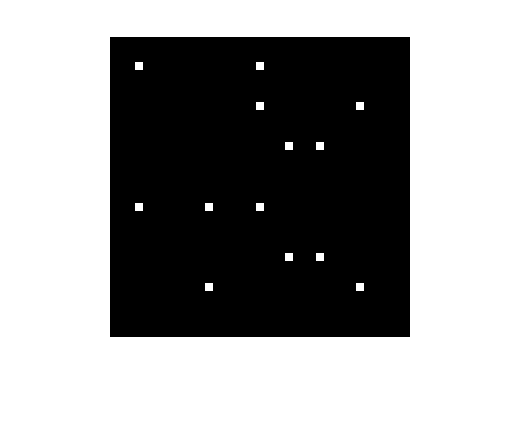

C = smoothedHessian(im1, 5, 5);
imshow(C(:,:,2,1));

% Do we need to use both?
% According to the result of the next question, 
% We do need to use both of sigma and epsilon

## D

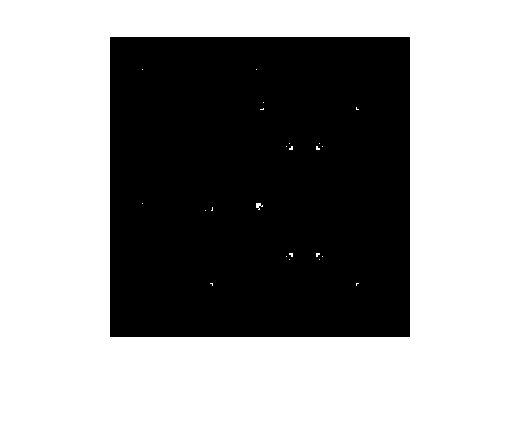

r = harrisMeasure(im1, 5, 5, 0.06); % typically, k is 0.06
imshow(r)

% Either we set sigma or epsilon 0, we got all r 0. 
% If epsilon is equal to 0, r shall always be 0, since it's always point
% operation
% We can find the corner points easily


## E

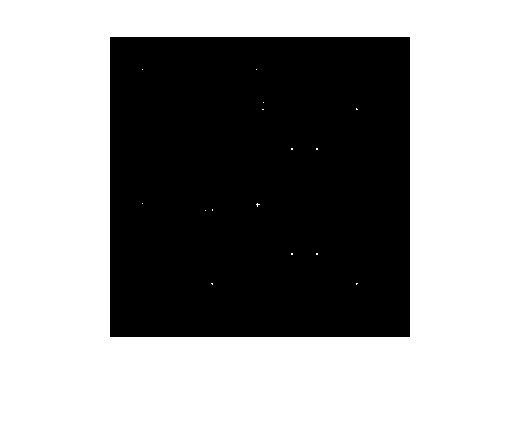

c = cornerDetector(im1, 5, 5, 0.06, 0.5);

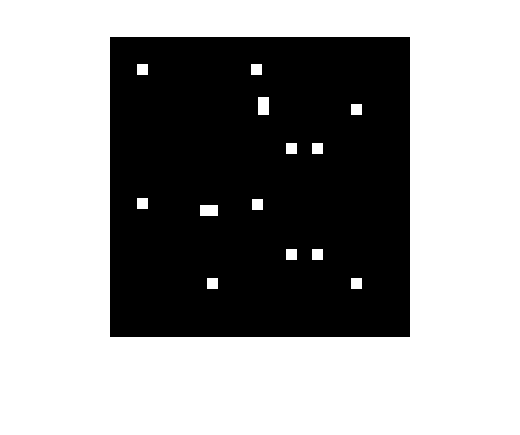

imshow(c)

% Find 2 more points

## F

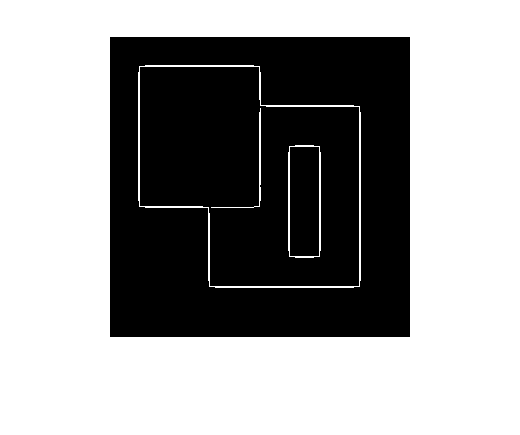

%Canny Edge Detection
b1 = edge(im1, 'Canny');
imshow(b1);

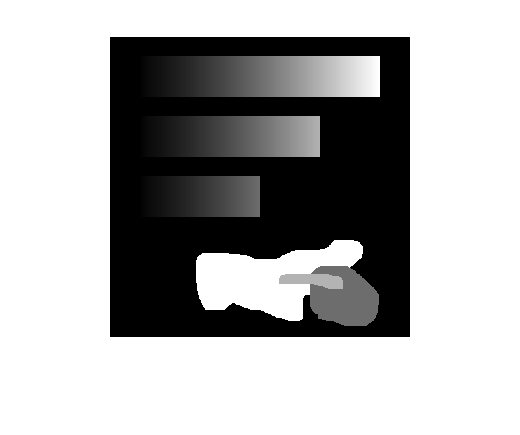

im2 = imread('TestIm2.png');
im2 = rgb2gray(im2);
imshow(im2);

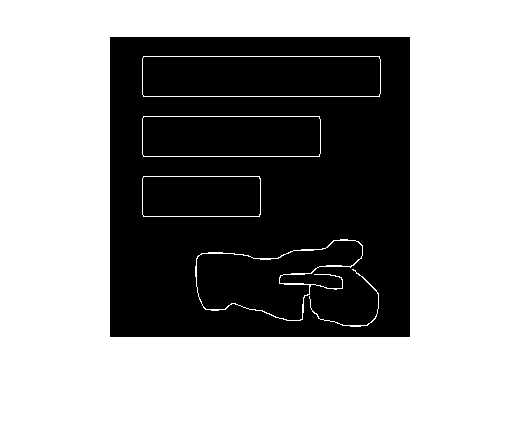

b2 = edge(im2, 'Canny');
imshow(b2);

## G

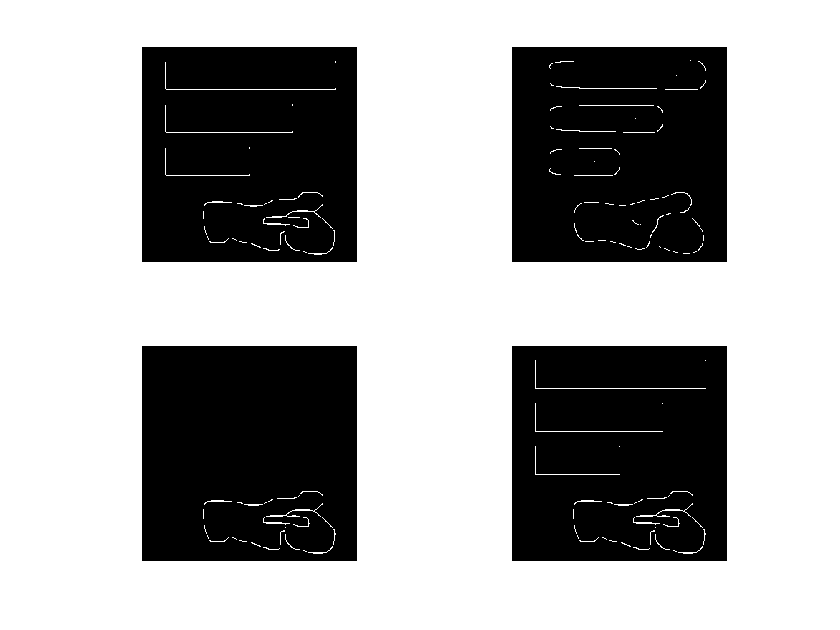

% Parameters 2 thresholds(0<thr<1) and sigma for gaussian blur
figure;
subplot(2,2,1);
imshow(b2);
b21 = edge(im2, 'Canny',[0.0313 0.0781], 10);
subplot(2,2,2);
imshow(b21);
b22 = edge(im2, 'Canny',[0.0313 0.99], 1);
subplot(2,2,3);
imshow(b22);
b23 = edge(im2, 'Canny',[0.0000001 0.0781], 1);
subplot(2,2,4);
imshow(b23);